# **Stellar Motion**

Determine a star's motion by calculating the redshift in its spectrum, using the Hydrogen-alpha ($H \alpha$) line.

(Note: When doing this project, the starData file was not given to me. The file used contains different data, so numbers will be strange. Script still works for the purpose of the project though.)

**Load data and define measurement parameters**

load starData.txt
spectra = starData

spectra =     0.9948    0.0232   -0.0995   28.0000    4.6100    3.0000
    0.9725    0.0242    0.2317   87.0000    5.5500    4.0000
    0.4351    0.0122    0.9003  144.0000    5.5700    7.0000
    0.9984    0.0337   -0.0445  315.0000    6.4300   11.0000
    0.9984    0.0357   -0.0427  352.0000    6.1800   14.0000
    0.8733    0.0320    0.4862  358.0000    2.0700   15.0000
    0.5124    0.0205    0.8585  432.0000    2.2800   21.0000
    0.9492    0.0375    0.3125  448.0000    5.5700   22.0000
    0.8823    0.0360   -0.4693  493.0000    5.4200   24.0000
    0.6972    0.0286   -0.7163  496.0000    3.8800   25.0000


nObs = size(spectra,1);
lambdaStart = 630.02;
lambdaDelta = 0.14;

**Create vector of wavelengths**

Calculate last wavelength

lambdaEnd = lambdaStart + (nObs-1)*lambdaDelta;

Make column vector of equally spaced wavelengths

lambda = (lambdaStart:lambdaDelta:lambdaEnd)';

**Extract spectrum of HD94028**

Extract the appropriate column of spectra

(In this project, we look at the spectra from the 6th given star)

s = spectra(:,6);

**Plot the spectrum**

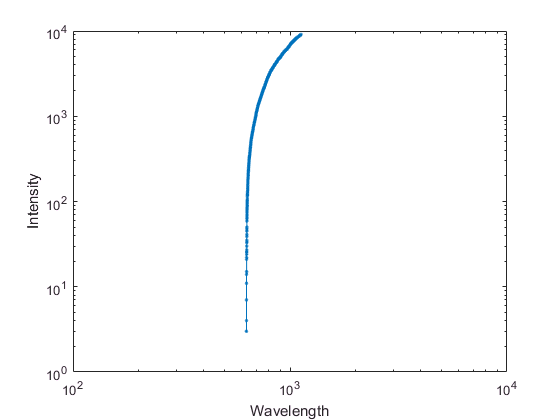

loglog(lambda,s,'.-')
xlabel('Wavelength')
ylabel('Intensity')

**Find the wavelength of the Hydrogen-alpha line**

Find the location of the minimum spectral value

[sHa,idx] = min(s);

Extract the corresponding wavelength

lambdaHa = lambda(idx);

## Show the Hydrogen-alpha line on the spectrum plot

**Task 1:** Add to the existing graph by plotting the single point  $x$= lambdaHa, $y$ = sHa as a red square ('rs') with a marker size ('MarkerSize') of 8.

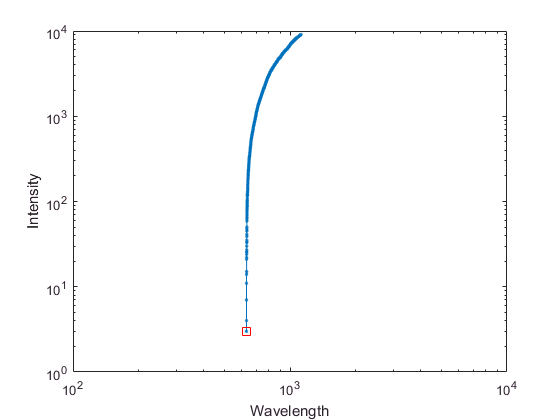

hold on;
x = lambdaHa;
y = sHa;
plot(x,y,'rs','MarkerSize',8)
hold off

## **Determine the redshift**

**Task 2 (a):** Calculate the redshift factor using the formula


$$$$z = \frac{\lambda_{H \alpha}}{\lambda^\mathrm{ref}_{H \alpha}} -1$$


where the reference wavelength for $H \alpha$ is $\lambda^{\mathrm{ref}}_{H \alpha} = 656.28$nm.

z = (lambdaHa/656.28)-1

z = -0.0400

## **Determine the stellar motion**

**Task 2 (b):** Calculate the rate that the star is moving away from the Earth (in km/s) using the formula


$$$$v = z \times c$$$$


where $c$ is the speed of light:$c = 299792.458$ km/s.

c = 299792.458;
speed = z*c

speed = -1.1996e+04